# **IO3xx - Optimized Data Transfer**

This example demonstrates how to use the **Optimized Data Transfer **option in the IO3xx Setup block. This option modifies the data transfer behavior between the configurable I/O module and the application running on the CPU, as well as the model trigger behavior. When **Optimized Data Transfer** is enabled, all driver blocks for the Configurable I/O specified with the fastest model rate combine their data transfers to and from the CPU into single optimized transfers (using DMA) before and after model execution. This reduces the portion of the task execution time (TET) for data transfers and results in more computation time being available on the CPU for highly demanding closed-loop applications.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO3xx I/O module installed

- A Speedgoat configuration file with functionality supporting the optimized data transfer (e.g., PWM Capture or Quadrature Decoder)

- A connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

The focus of this example is the PWM Capture v1 driver block. A PWM Generation v5 block is used to complete the loopback setup. The exact pins depend on your specific configuration file (bitstream). Use the **Pin Mapping** button in the Setup block to locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires.

Note that this example is prepared for 8 PWM-CAP connections. You can also use fewer connections if you have less channels available in your configuration file.

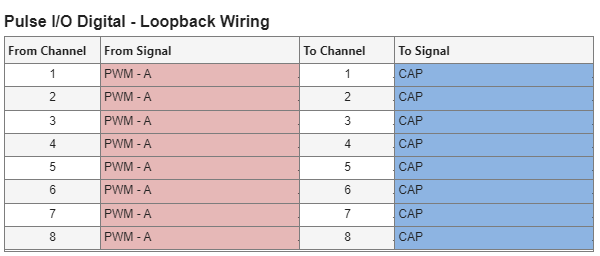

## Initialize and Open the Simulink Model

Open the Simulink model manually or use the following commands.

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_OptimizedDataTransfer';
open_system(modelName);

% specify sample times
Ts = 1e-3;   % base rate
Tcap = 1e-3; % CAP sample time

Before building the Simulink model, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

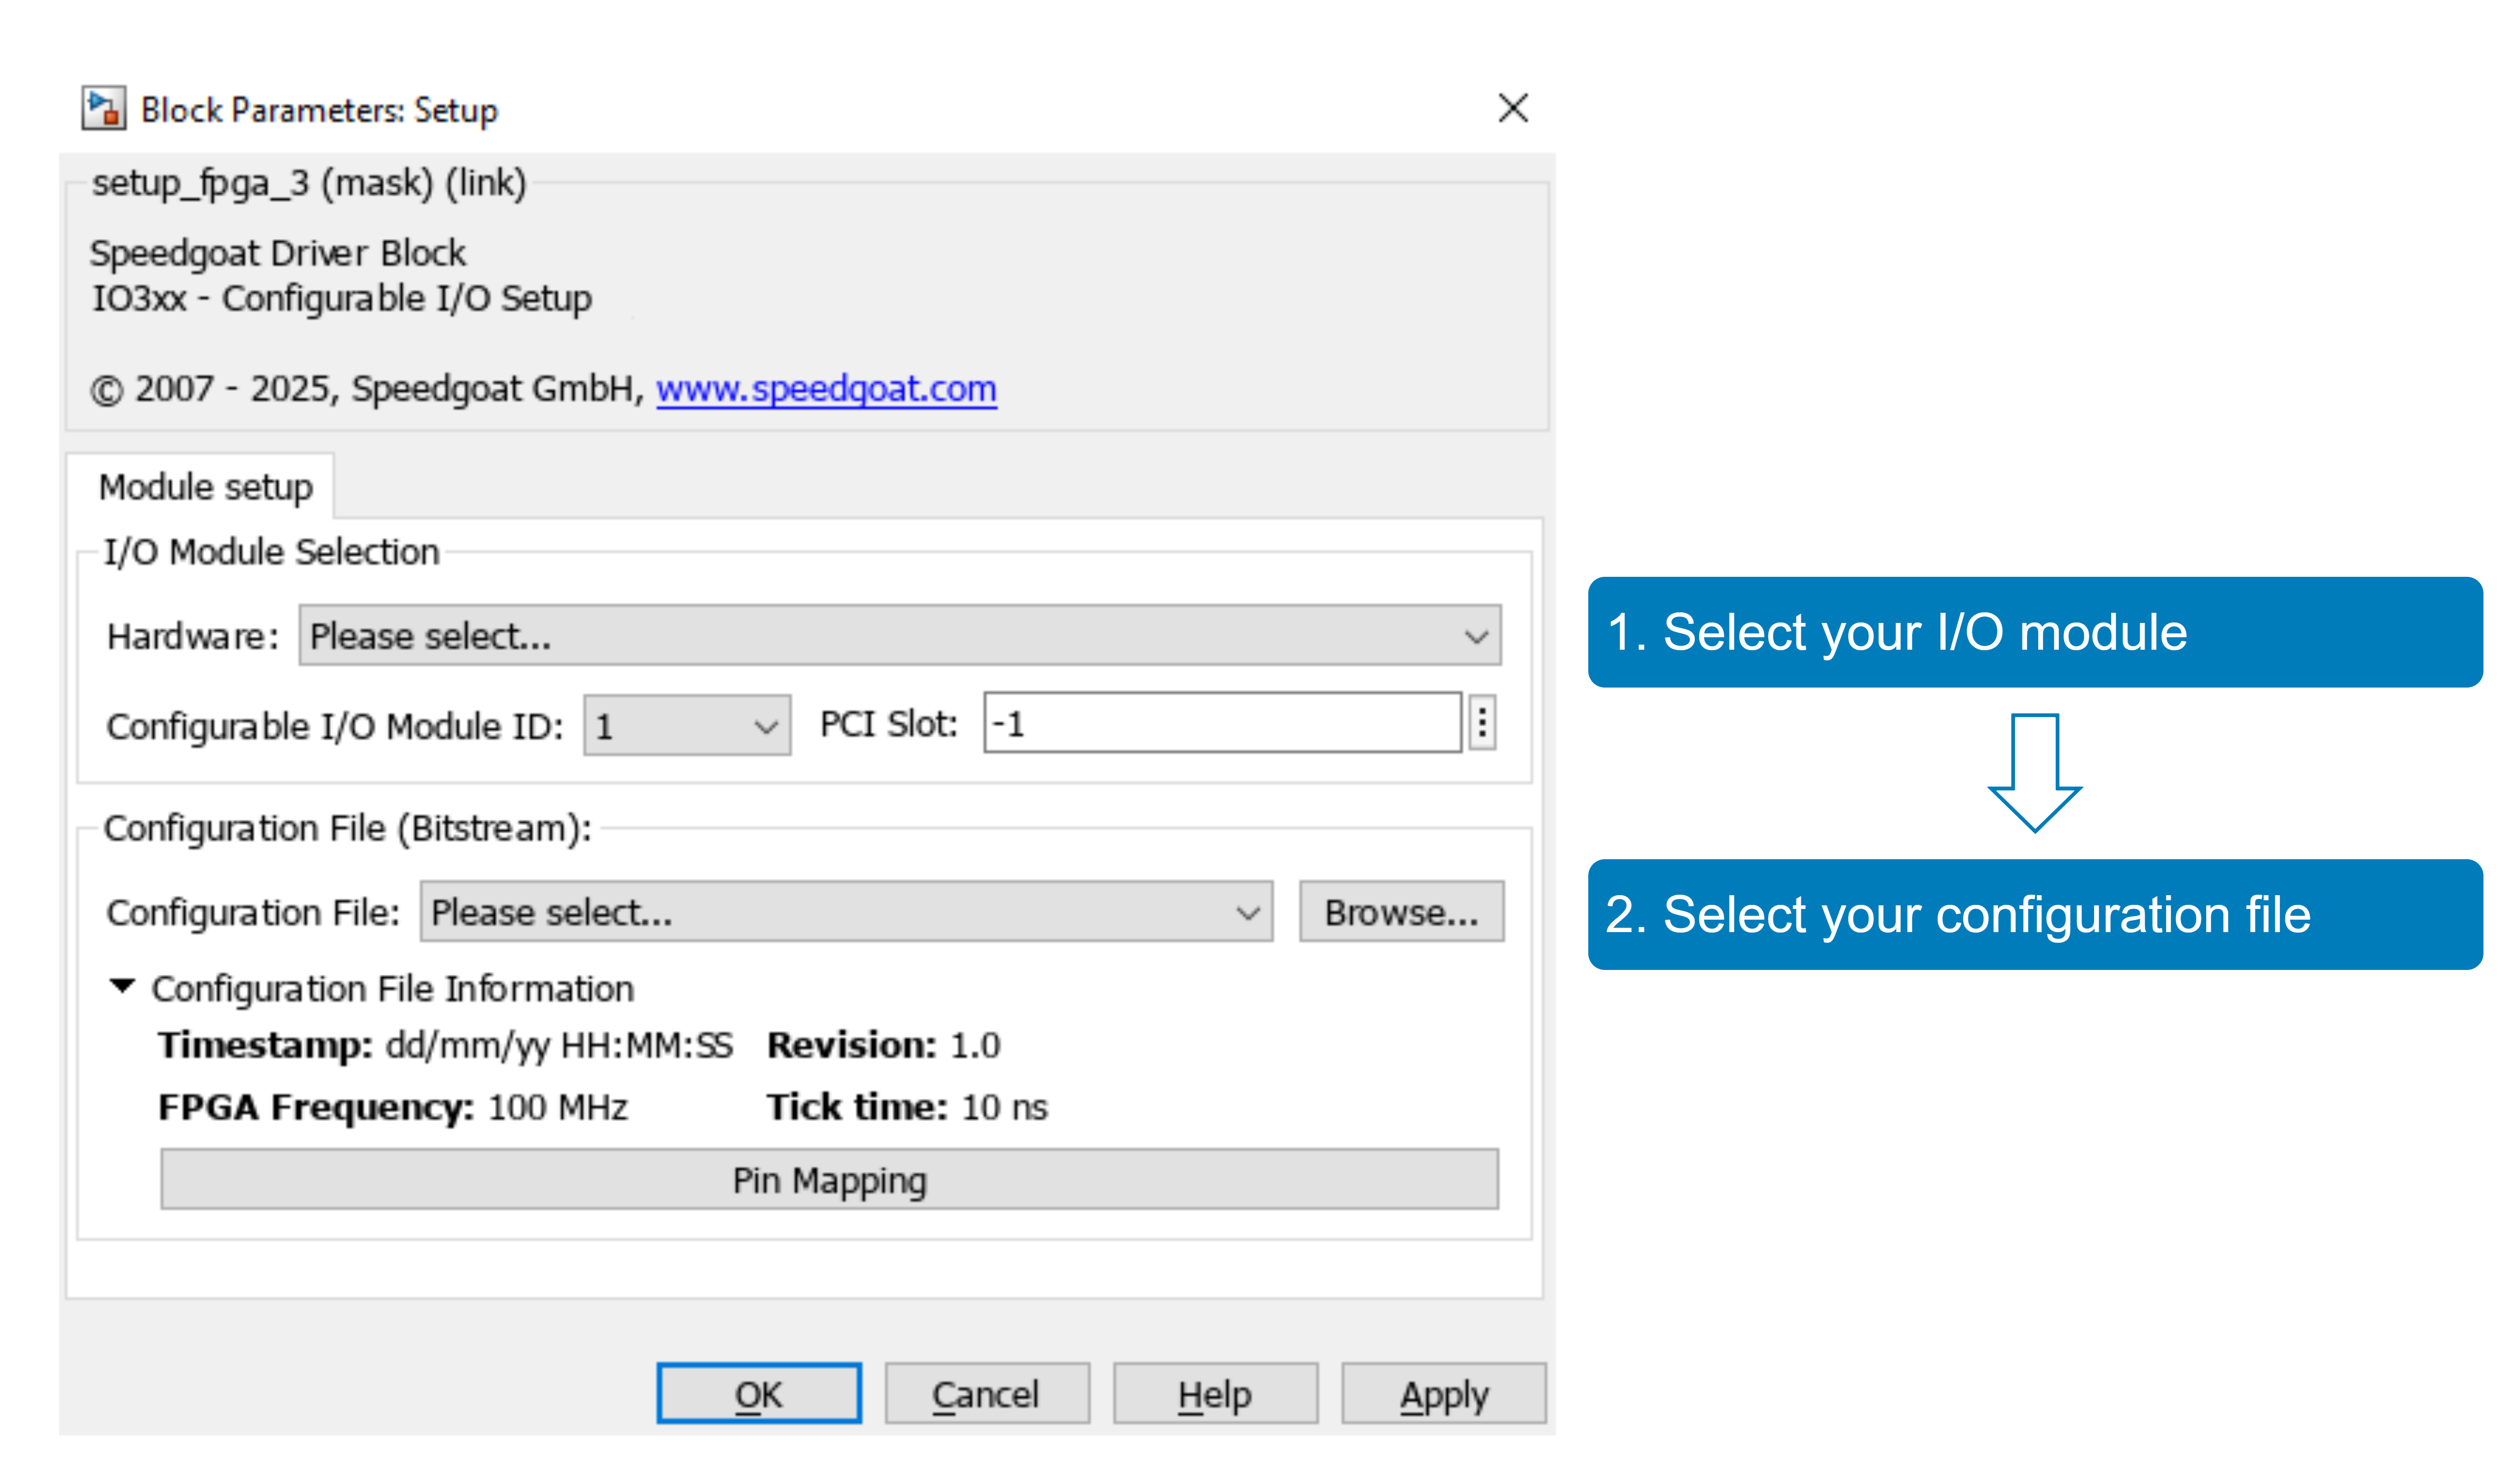

Click the **Pin Mapping** button to view the details of your configuration file. On the first tab, you can verify which pins the functionalities use. On the **Details** tab, the **Code Module Functionalities** table displays the implemented code modules, the number of channels, the code module version and whether optimized data transfer is supported.

Verify that your CAP code module version supports optimized data transfer. If it does not, your selected configuration file is not compatible with this example.

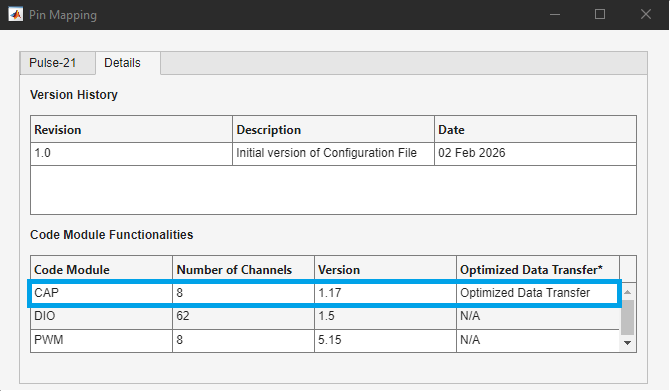

## Model Description

### General Setup

The Simulink model features the [IO3xx I/O Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx), [PWM Generation v5](https://www.speedgoat.com/help/slrt/page/io_main/refentry_pwm_generation_v5), and the [PWM Capture v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_pwm_capture_v1) driver blocks.

This example runs the model twice to demonstrate the impact of optimized data transfer on the TET, and the synchronization between the configurable I/O module and the model. The TET indicates the computational load of the real-time application at each time step. In this single-rate model, the TET measurement is available at the TET output of the Overload Options block.

By default, the Simulink model running on the CPU is triggered by a timer and each block in the model sequentially communicates with the configurable I/O module. The more blocks there are, and the more channels are active, the more communication needs to be done which will ultimately result in higher TET. For highly demanding closed-loop applications with high sample rates, this might lead to CPU overloads. Additionally, a CPU also running other background tasks and the timer used will cause a slight jitter (time variation) between sample steps. For high precision measurements this might lead to inaccuracies.

The **Optimize Data Transfer** option improves TET and synchronization. It samples and latches all the required data very precisely with the configured sample time configured (zero jitter) and combines all data transfers between the configurable I/O module and the CPU into a single transfer. Instead of using the CPU timer, the model will be triggered by the configurable I/O module as soon as all the read data is fully transferred to the CPU. When the model executes, all data for computation is already present, which reduces the TET. After model execution, the write data is also written to the configurable I/O module in the background. With this optimized setup, the TET measurement in the model will be reduced, as the data transfers for read and write accesses are excluded from the measurement. The time required for the data transfer is also important when considering the maximum achievable closed-loop rate. To monitor the overall turnaround time, the [DMA Controller](https://www.speedgoat.com/help/slrt/page/io_main/refentry_dma_controller_v1) block provides a duration port, that includes data transfer and TET in its measurement.

### PWM Generation

The model contains one instance of the PWM Generation v5 block. The block is assigned to PWM channels 1 to 8 and configured to generate symmetric PWM signals for each channel. The period is set to 1 ms, matching the model base rate. The input signal to the block defines the duty cycle and must be in the range between 0 and 1. This example uses a sine-wave-shaped duty cycle signal with different amplitude for each of the eight PWM channels.

### PWM Capture

The model contains one instance of the PWM Capture v1 block. The block is assigned to CAP channels 1 to 8. The high duration, low duration, and period outputs are enabled in the **Input and Output Configuration** tab of the block mask. Note that all outputs are enabled for this example to demonstrate multiple read accesses from the Configurable I/O module. In production applications, only enable the outputs you need to minimize latency.

The **Capture Mode** is set to **Software Triggered**. The PWM capture module on the FPGA averages the incoming signal over the duration of one CPU model sample step. In this example, the CPU sample step equals the duration of the configured PWM period. Note that the interval between consecutive PWM Capture v1 driver block executions on the CPU is subject to jitter due to variable timer latency and computational load on the real-time target.

## Build, Download, and Run the Example

To run the example, either run the following code sections or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

### Run1

For the first run, **Optimized Data Transfer** and **IO3xx controlled** are disabled.

Build, deploy, and run the model on the real-time target machine.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Set the stop time of the real-time application to 10 seconds
tg.setStopTime(10)

% Start the real-time application
tg.start;

% Wait a few seconds until the real-time application on the target machine is stopped
pause(10)


### Check the Results

Open the Simulink scope in the model to verify that the loopback executed correctly. Scope 1 displays:

**Left:** The high time, low time, and period measured for the 8 PWM signals.

**Right:** The TET of the single-rate model in seconds.

The following figure shows the results of the first run with **Optimized Data Transfer** disabled. You can see that the high time is the complement of the low time. Note that the period exhibits some jitter. This jitter is expected because the CAP module is triggered by the execution of the PWM Capture block on the CPU, which is subject to variable timer latency and computational load.

The average TET is approximately 12.5 µs. This includes the computational load of the entire model, including both the PWM Generation and Capture driver blocks.

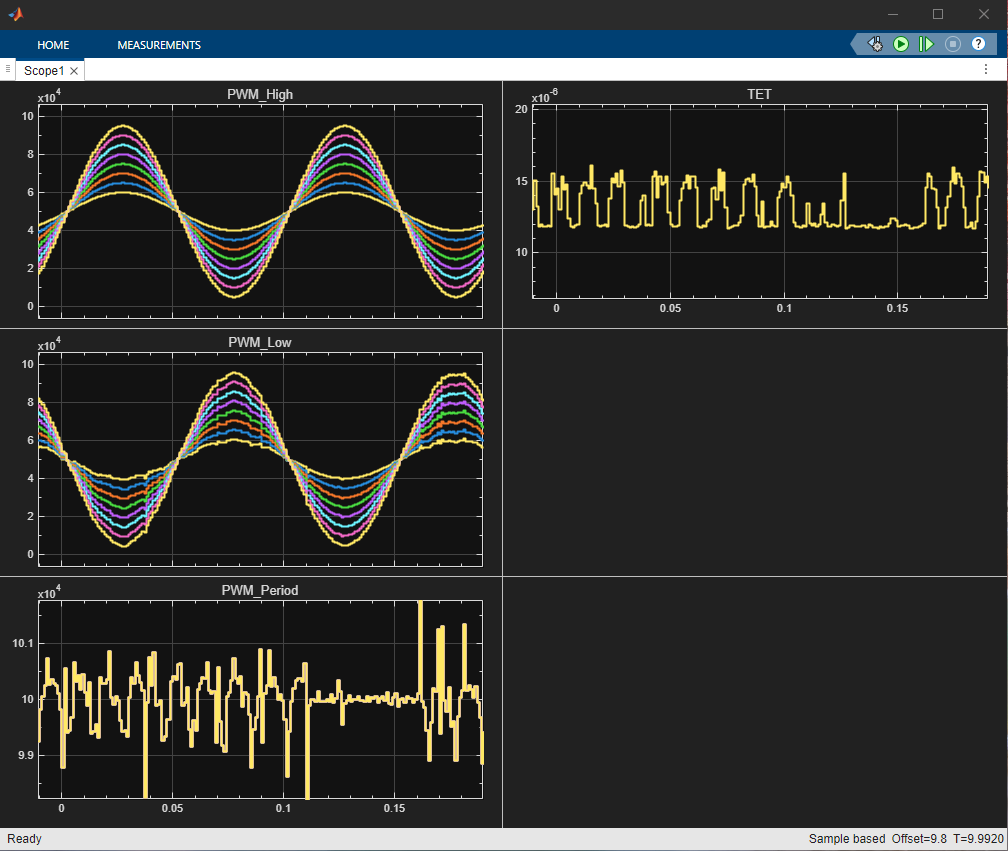

### Run 2

For the second run, enable **Optimized Data Transfer** in the IO3xx Setup block by selecting the **IO3xx controlled** checkbox. Then, click the **Add Interrupt Setup block** button to add a pre-configured Interrupt Setup block to your model.

The Interrupt Setup block synchronizes the model to the IO3xx and its data transfer.

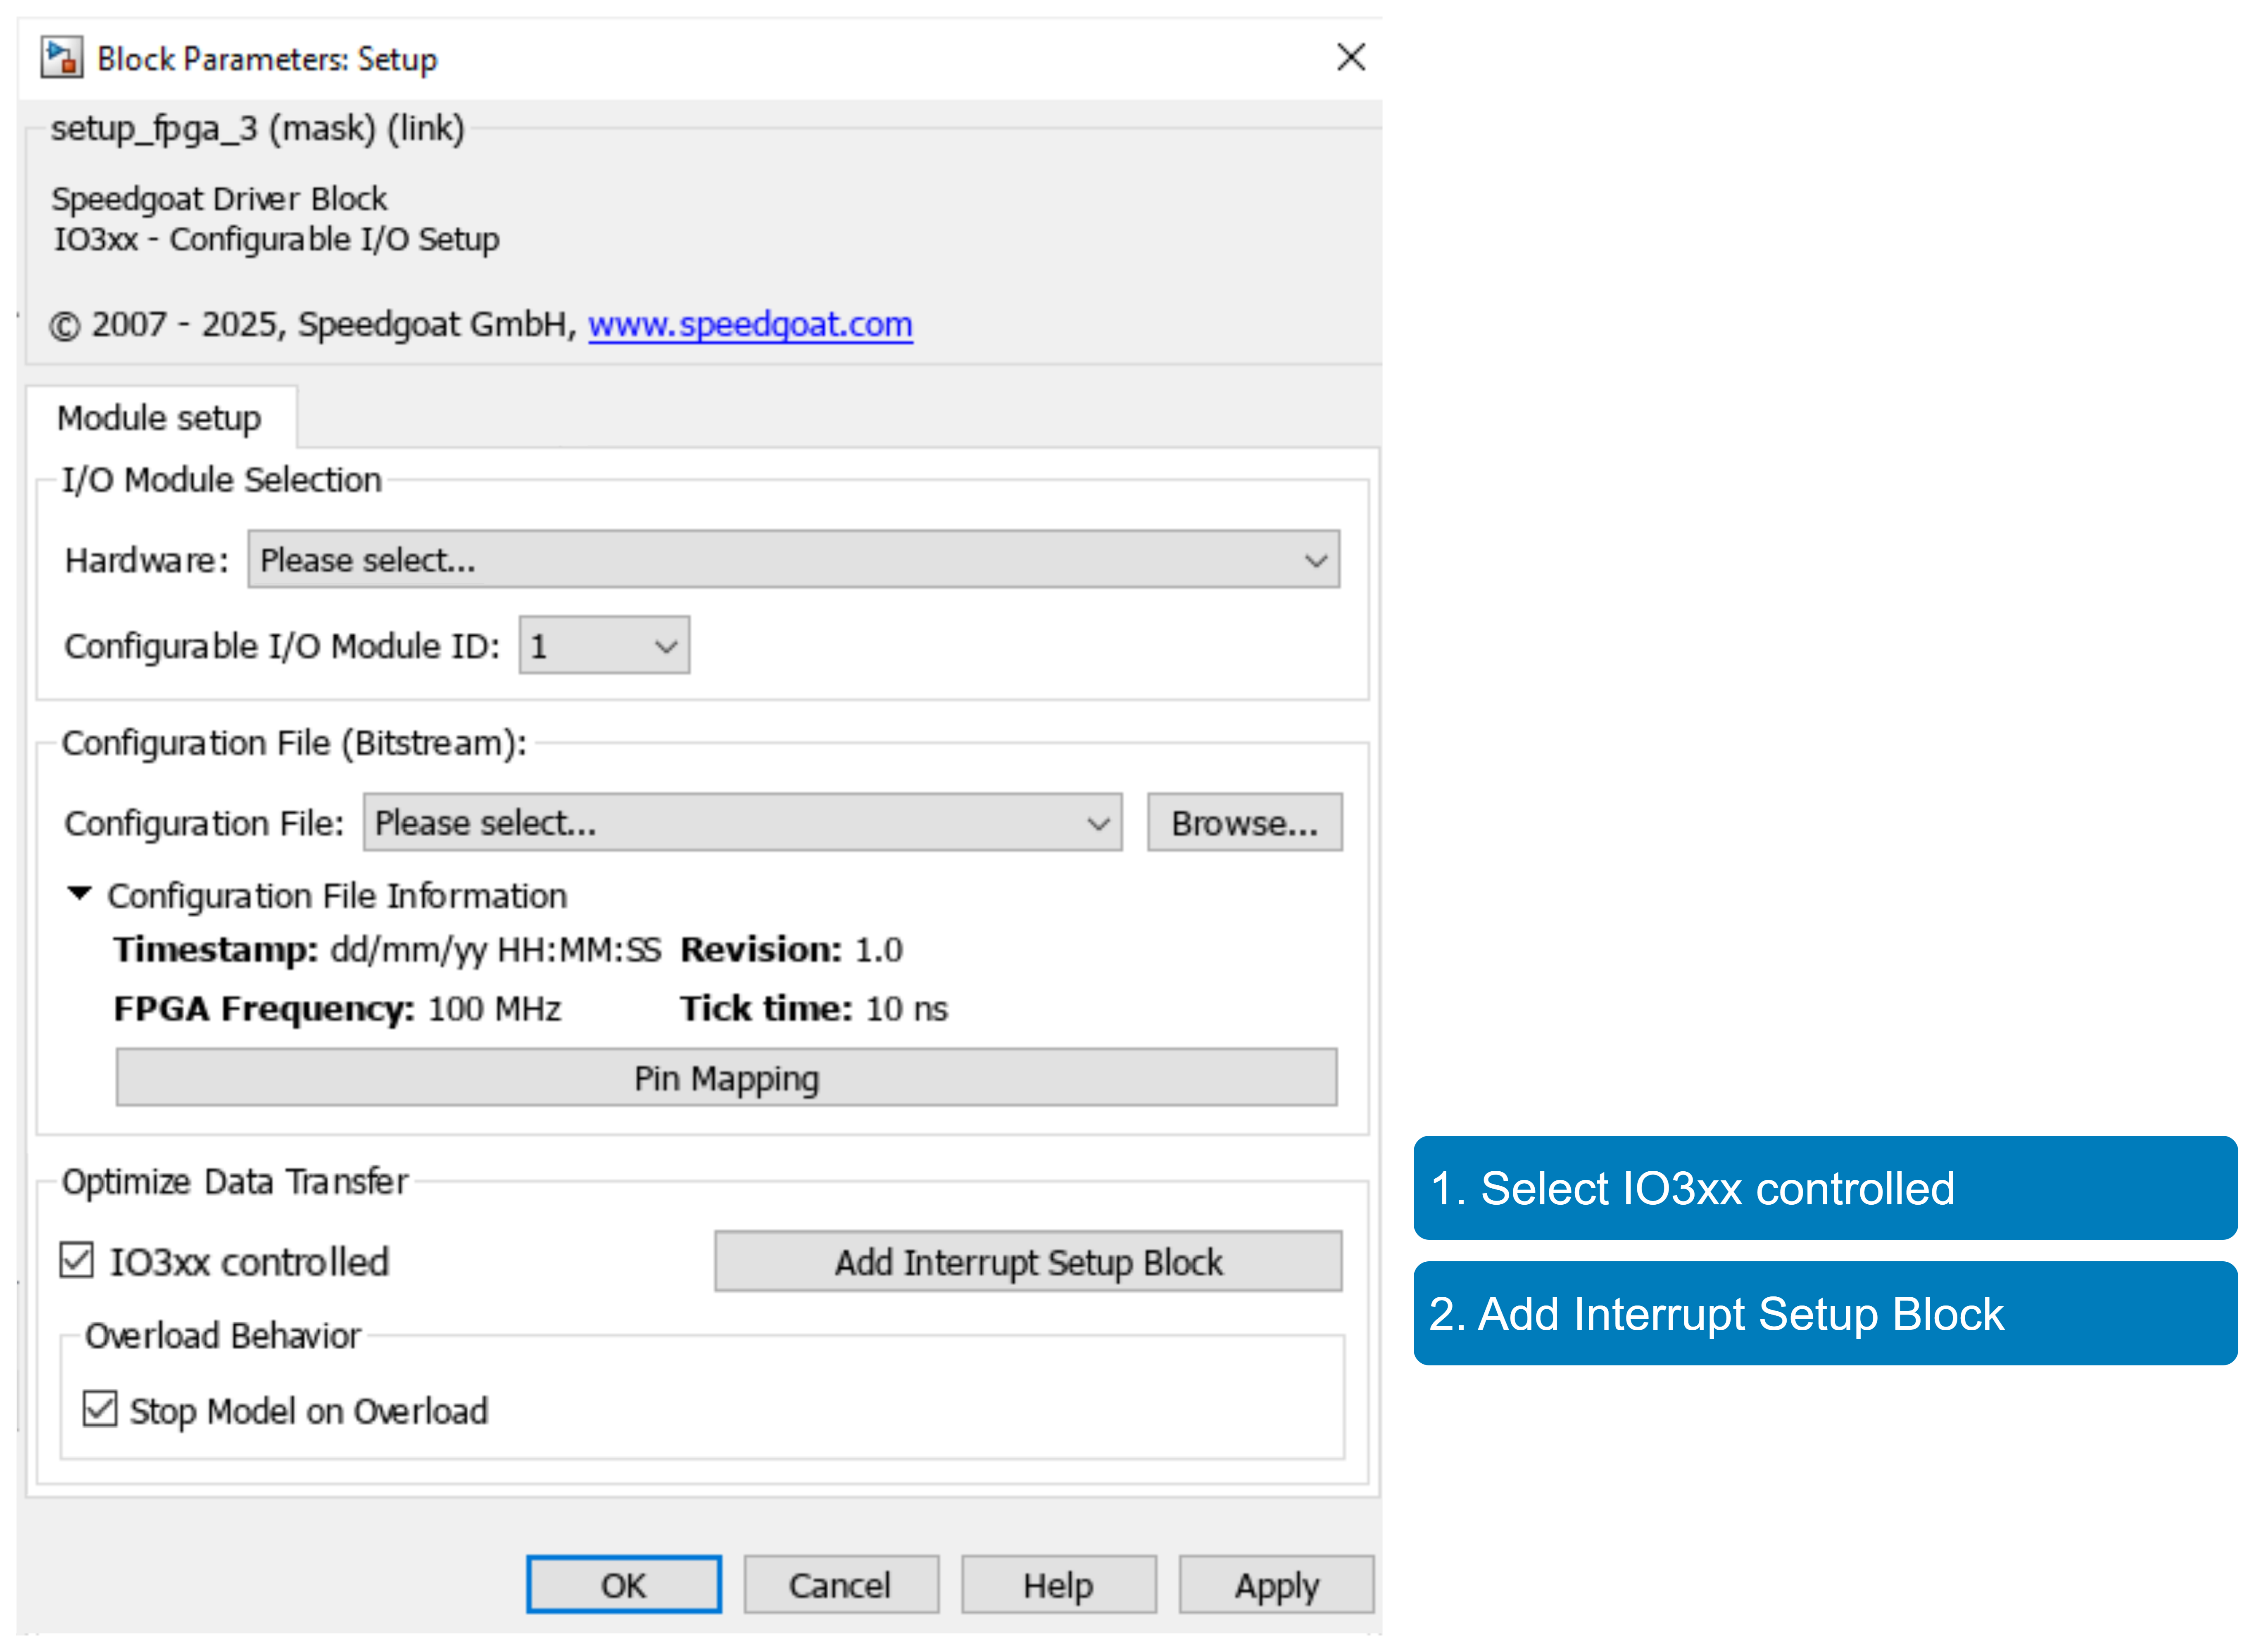

Open the mask of the Interrupt Setup block added. The block is configured to use the **Speedgoat IO3xx FPGA polling** interrupt, which enables the **Use as Model Trigger** and **Use in Polling Mode** parameters. The model base rate is now triggered by the configurable I/O module.

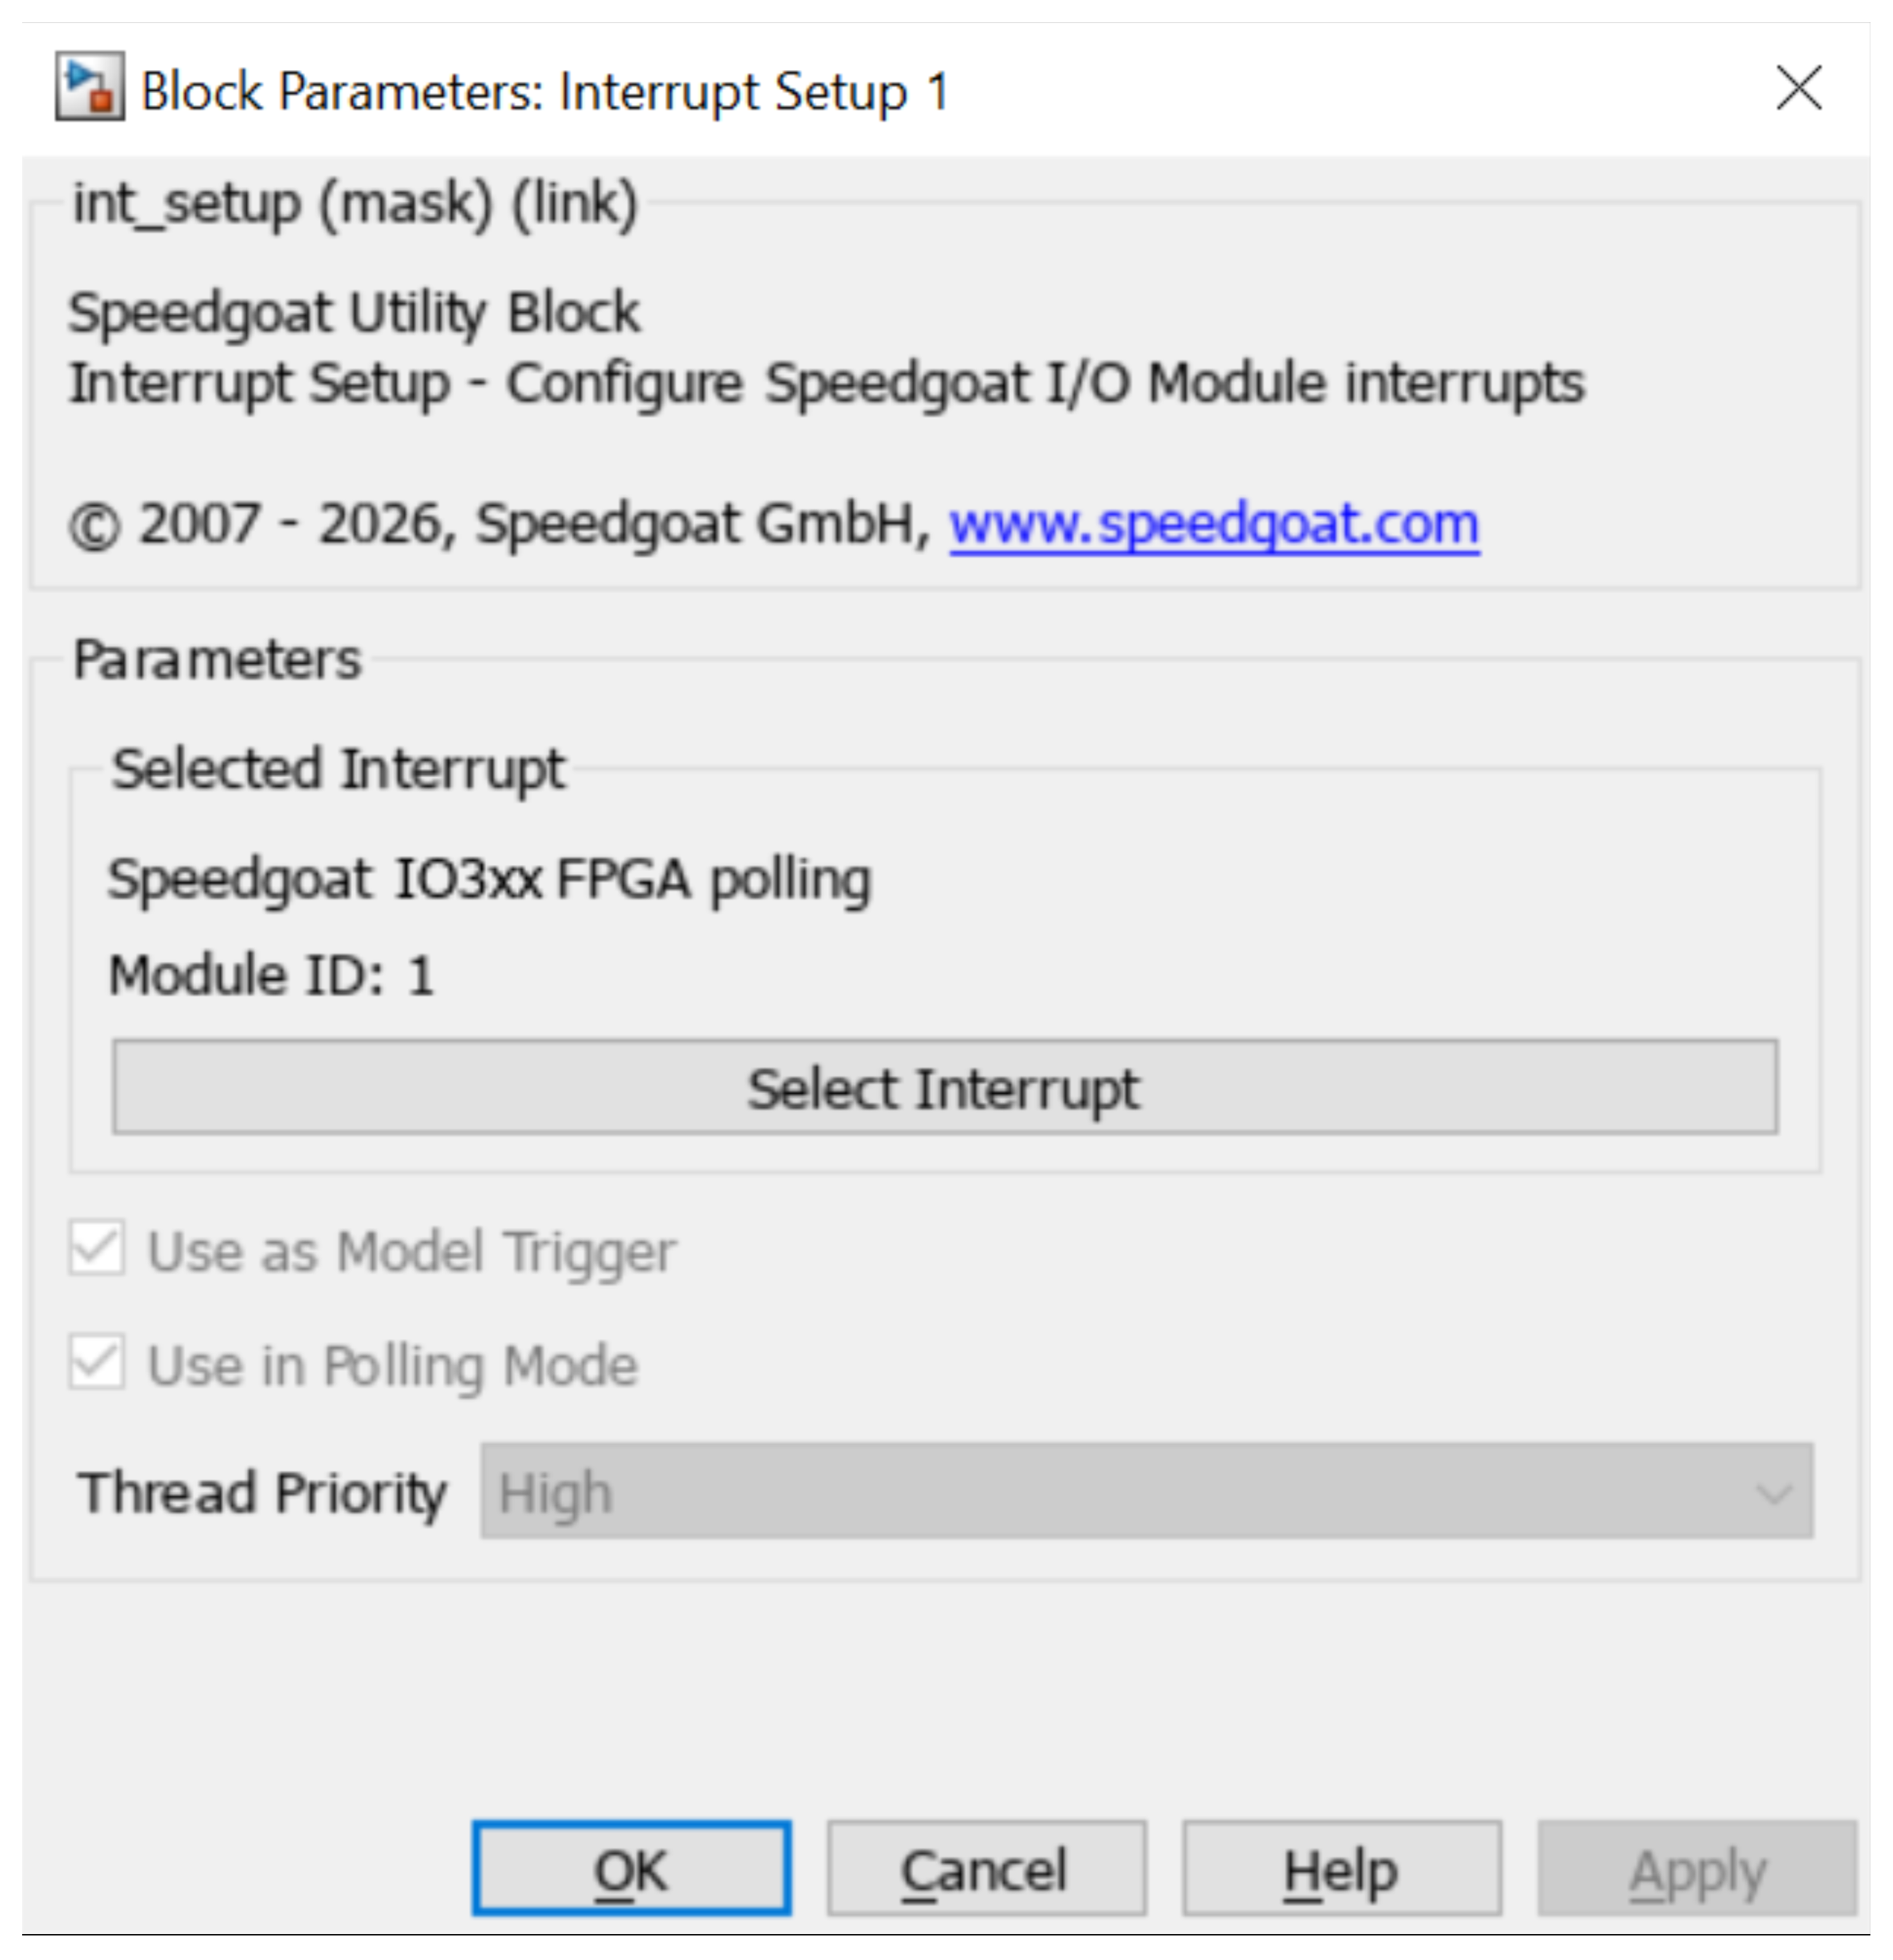

Now rebuild, deploy, and run the model on the real-time target machine.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Set the stop time of the real-time application to 10 seconds
tg.setStopTime(10)

% Start the real-time application
tg.start;

% Wait a few seconds until the real-time application on the target machine is stopped
pause(10)

### Check the Results

Open the Simulink scope to compare the results with the first run. The following screenshot shows the results of the second run.

On the left, you can see the effect of synchronization to the configurable I/O module. The PWM period measured is now exactly 1 ms because all the data captured is independent of the model execution on the CPU.

On the right, the TET drops to approximately 9 µs. The PWM Capture block data is already transferred before the model sample step, which reduces computational load. This reduction in computational load becomes more significant when more data is read, more functionalities are used, or more channels are active than shown in this example.